# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 2.12.12 Spotlight SAR Pulse Repetition Frequency

## Calculate the pulse repetition upper and lower limits

$\frac{2{v\;L}_{\textrm{sa}} \;}{\lambda \;R_0 }\le \textrm{PRF}\le \frac{c}{2\;R_u }\left(\textrm{Hz}\right)$   Equation (2.41)

% Clear the workspace
clear

% Operating frequency (Hz)
operating_frequency = 12e9;

% Synthetic aperture length (m)
aperture_length = 350;

% Unambiguous range (m)
unambiguous_range = 250e3;

% Platform velocity (m/s)
velocity = linspace(50, 300, 1e3);

% Slant range to imaging area (m)
slant_range = 20e3;

% Calculate the wavelength (m)
wavelength = 299792458 / operating_frequency;

% Calculate the upper limit (Hz)
prf_upper_limit = 299792458 / (2 * unambiguous_range) .* ones(1, length(velocity));

% Calculate the lower limit (Hz)
prf_lower_limit = 2 * velocity * aperture_length / (wavelength * slant_range);

## Plot the results

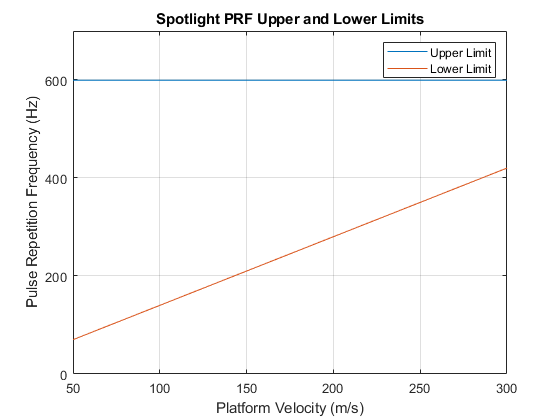

figure;
plot(velocity, prf_upper_limit); hold on
plot(velocity, prf_lower_limit)
xlabel('Platform Velocity (m/s)')
ylabel('Pulse Repetition Frequency (Hz)');
title('Spotlight PRF Upper and Lower Limits');
legend('Upper Limit', 'Lower Limit');
ylim([0, 700]);
yticks([0, 200, 400, 600, 800])
grid on